# main

clc;
disp('Programa para ....');

Programa para ....


numNodos = input('Ingrese cuantos nodos tiene: ');
numResistencias = input('Ingrese el numero de resistencias: ');
matrizResistencias = leerResistencias(numResistencias);

disp('Matriz de resistencias: ');

Matriz de resistencias: 


disp('/n| Resistencias | Nodo A| Nodo B |');

/n| Resistencias | Nodo A| Nodo B |


disp(matrizResistencias);

   100     1     2
    50     2     3
   150     1     0
   200     2     0
   100     3     0




matrizDeConductancia = sumaResistencias(matrizResistencias, numNodos);

resistencia = 100

n1 = 1

n2 = 2

resistencia = 50

n1 = 2

n2 = 3

resistencia = 150

n1 = 1

n2 = 0

resistencia = 200

n1 = 2

n2 = 0

resistencia = 100

n1 = 3

n2 = 0

disp(matrizDeConductancia);

   250  -100     0
  -100   350   -50
     0   -50   150






function resistencias = leerResistencias(n)

    resistencias = zeros(n,3);

    for i = 1:n
        valor = input('ingrese el valor de la resistencia: ');
        nodoA = input('Ingrese el nodo A: ');
        nodoB = input('Ingrese el nodo B: ');

        resistencias(i, :) = [valor, nodoA, nodoB];

    end
end

function G = sumaResistencias(matrizResistencias, numNodos)
    G = zeros(numNodos);
    for i = 1:size(matrizResistencias,1)
        resistencia  = matrizResistencias(i,1)
        n1 = matrizResistencias(i,2)
        n2 = matrizResistencias(i,3)

        if n1 ~= 0
            G(n1,n1) = G(n1,n1) + resistencia;
        end
        if n2 ~= 0
            G(n2,n2) = G(n2,n2) + resistencia;
        end
        if n1 ~= 0 && n2 ~= 0
            G(n1,n2) = G(n1,n2) - resistencia;
            G(n2,n1) = G(n2,n1) - resistencia;
        end
    end
end


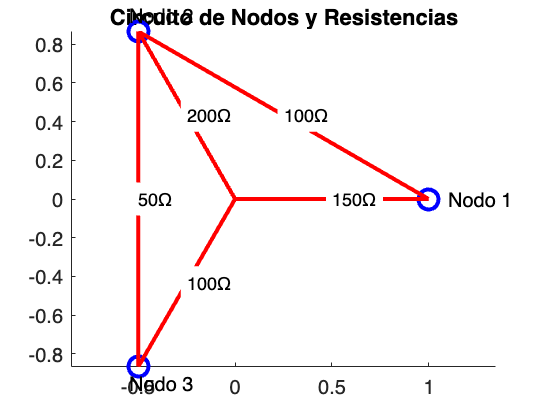

%% Visualización del circuito

% Extraemos datos
valores = matrizResistencias(:,1);
nodoA = matrizResistencias(:,2);
nodoB = matrizResistencias(:,3);

% Asignamos posiciones en círculo para los nodos
theta = linspace(0, 2*pi, numNodos+1);
theta(end) = []; % Eliminar duplicado
x = cos(theta);
y = sin(theta);

% Graficar nodos
figure;
hold on;
axis equal;
title('Circuito de Nodos y Resistencias');
for i = 1:numNodos
    plot(x(i), y(i), 'bo', 'MarkerSize', 10, 'LineWidth', 2);
    text(x(i)*1.1, y(i)*1.1, sprintf('Nodo %d', i), 'FontSize', 10);
end

% Graficar resistencias como líneas
for i = 1:length(valores)
    a = nodoA(i);
    b = nodoB(i);
    r = valores(i);

    % Si alguno de los nodos es tierra (0), lo conectamos al centro
    if a == 0
        xa = 0; ya = 0;
    else
        xa = x(a); ya = y(a);
    end
    if b == 0
        xb = 0; yb = 0;
    else
        xb = x(b); yb = y(b);
    end

    % Dibujar línea
    plot([xa xb], [ya yb], 'r-', 'LineWidth', 2);

    % Etiqueta en el punto medio
    xm = (xa + xb)/2;
    ym = (ya + yb)/2;
    text(xm, ym, sprintf('%.0fΩ', r), 'BackgroundColor','white', 'FontSize', 9);
end

hold off;